new_x=load("RF_data.mat");

%Load images of 2 percent calcium carbonate
%imshow(RF_caco3_2perc{1, 1}{1, 1});
%image(RF_caco3_2perc{1, 1}{1, 1});


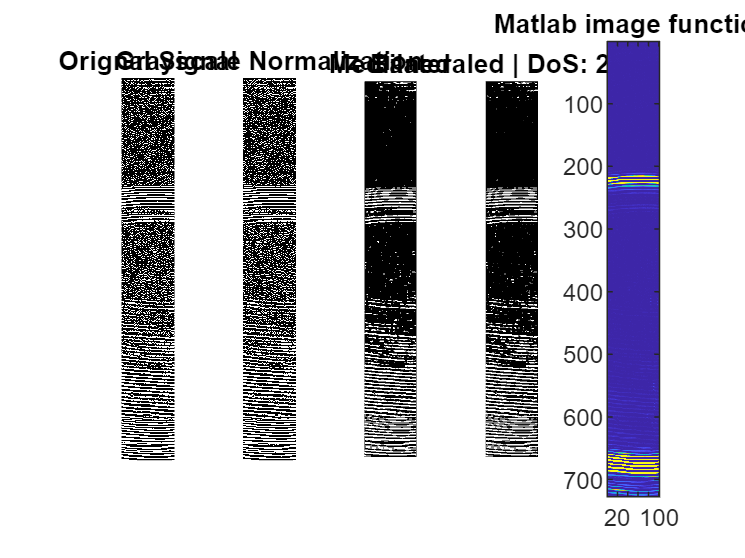

figure;
%Load images of 2 percent calcium carbonate
subplot(1,5,1)

imshow(RF_ag{1, 1}{1, 1})
title("Orignal Signal")
og = RF_ag{1, 1}{1, 1};


%Grayscale Normalization
subplot(1,5,2)

gNdata = uint8(255*og);
imshow(gNdata)
title("Grayscale Normalization")

%median Filter
subplot(1,5,3)

imgFilt0 =  medfilt2(gNdata, [4 4]);
imshow(imgFilt0)
title("Medianed")

%{
%Hilbert and removing negative values
hilbertedData = imag(hilbert(imgFilt0));

hilbertedData(hilbertedData<0) = 0;
imshow(hilbertedData)
title("Hilberted Data")
%}



%denoise

%Bilateral Filter
patch = imcrop(imgFilt0,[0, 0, 75, 75]); 
patchVar = std2(patch)^2;

DoS = 2*patchVar; %Degree of Smoothing
J = imbilatfilt(imgFilt0,DoS,3);   

subplot(1,5,4)
imshow(J)
title(['Bilateraled | DoS: ',num2str(round(DoS,0))])

%{

%Histogram Equalization
a = histeq(J);
imshow(a)
title("Histogram Equalization")
imhist(a)


%}

subplot(1,5,5)
image(RF_ag{1, 1}{1, 1})
title('Matlab image function')